# Trilateration based on RSSI values in transmitters and receivers

[Jerry Landivar G.](https://orcid.org/0000-0002-2983-0097), [Carolina Ormaza C.](https://orcid.org/0000-0002-3856-3162), [Víctor Asanza](https://orcid.org/0000-0002-2786-4162), [Verónica Ojeda C.](https://orcid.org/0000-0002-1526-5824), [Juan Carlos Aviles](https://www.fiec.espol.edu.ec/es/cv/avil%C3%A9s-castillo-juan-carlos)

- Main Code: [https://github.com/vasanza/WiFi_RSSI_Localization](https://github.com/vasanza/WiFi_RSSI_Localization)

- `SRC: `[https://github.com/vasanza/Matlab_Code](https://github.com/vasanza/Matlab_Code)

- `DataPort: `[https://dx.doi.org/10.21227/kjta-6551](https://dx.doi.org/10.21227/kjta-6551)

- `Reference: `

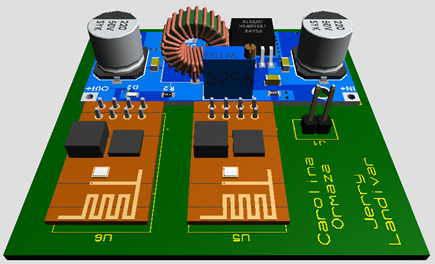

# 1- Load Raw Data

clear;clc;%clear all
%Prepare the raw dataset
addpath(genpath('./src'))%functions folders
datapath = fullfile('./data/');%data folder
filenames = FindCSV(datapath);%List All CSV files
allData=[];
for i=1:length(filenames)% Through all files
    data=readtable(fullfile(datapath,filenames(i).name));%Select i CSV file
    data=[data(2:size(data,1),1:3) data(2:size(data,1),5:104)];
    dataNew=table2array(data);% Array Double
    dataNew(isnan(dataNew)) = 0;%Remove NAN numbers

    for j=1:3:length(dataNew)-2
       AP0=dataNew(j,4:103);
       AP1=dataNew(j+1,4:103);
       AP2=dataNew(j+2,4:103);
       Q=dataNew(j,1)*ones([1,length(AP0)]);
       x=dataNew(j,2)*ones([1,length(AP0)]);
       y=dataNew(j,3)*ones([1,length(AP0)]);
       DataColum=[Q' x' y' AP0' AP1' AP2'];
       allData=[allData;DataColum];
    end
end
%Example
%Cuadricula, X, Y, AP0, AP1, Ap2
%1,10,190,56,-74,-69
%.
%.
%%1,10,190,21,-25,-32

clear data i AP0 AP1 AP2 Q x y j DataColum dataNew 

# 2- Plot Raw Data (Dataset)

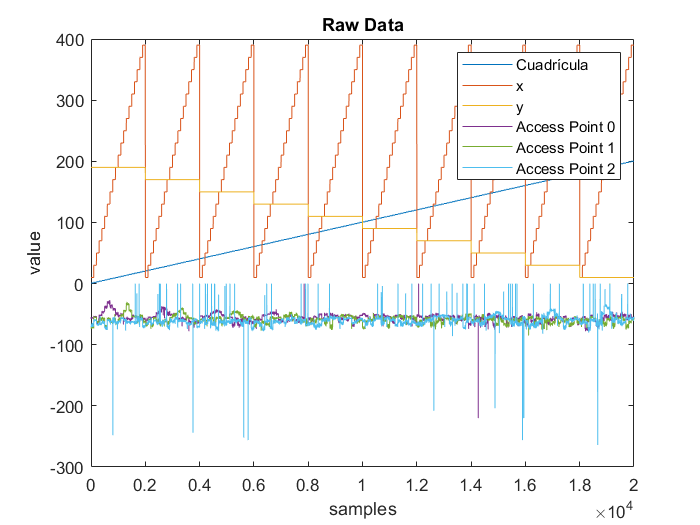

figure
plot(allData(:,:));title('Raw Data');xlabel('samples');ylabel('value');
%Cuadrícula; x; y; Access Point 0; Access Point 1; Access Point 2
legend('Cuadrícula', 'x', 'y', 'Access Point 0', 'Access Point 1', 'Access Point 2');

clear legend filenames datapath

# 3- Randomize rows

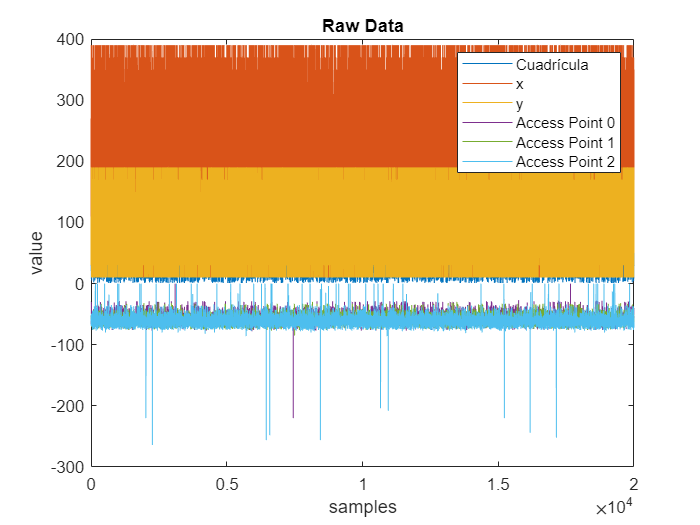

[RallData,IndexRows]=fRandomize_DataRows(allData);

figure
plot(RallData(:,:));title('Raw Data');xlabel('samples');ylabel('value');
%Cuadrícula; x; y; Access Point 0; Access Point 1; Access Point 2
legend('Cuadrícula', 'x', 'y', 'Access Point 0', 'Access Point 1', 'Access Point 2');

# 4- Preprocessing Raw Data (Filtering and Normalization)

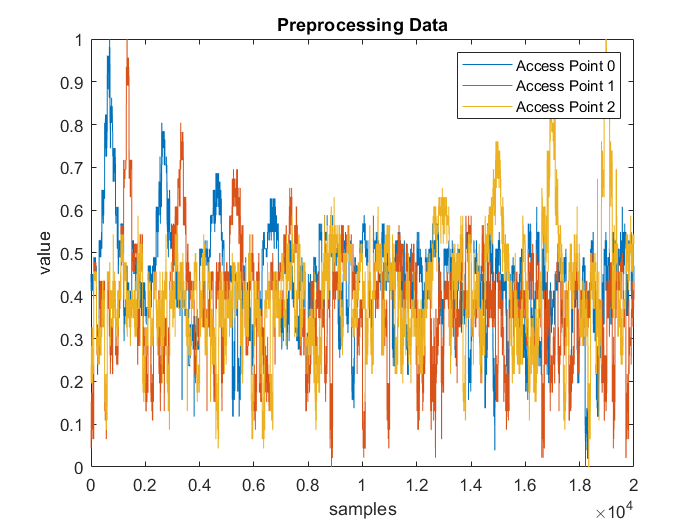

InputData=[];
for i=1:100:size(allData(:,4:6),1)-99
    InputData = [InputData; [hampel(allData(i:i+99,4)) hampel(allData(i:i+99,5)) hampel(allData(i:i+99,6))]];
end
DeNormMax=max(InputData(:,:));
DeNormMin=min(InputData(:,:));
InputDataNorm = fNormalization(InputData(:,:));%Data Normalization
% Access Point 0; Access Point 1; Access Point 2
Output = allData(:,1:3);%Data Output -> Cuadrícula; x; y;
plot(InputDataNorm(:,:));title('Preprocessing Data');xlabel('samples');ylabel('value');
legend('Access Point 0', 'Access Point 1', 'Access Point 2');

clear DataColum i allData

# [5] - Feature Extraction (RRSI measurements have already been averaged)

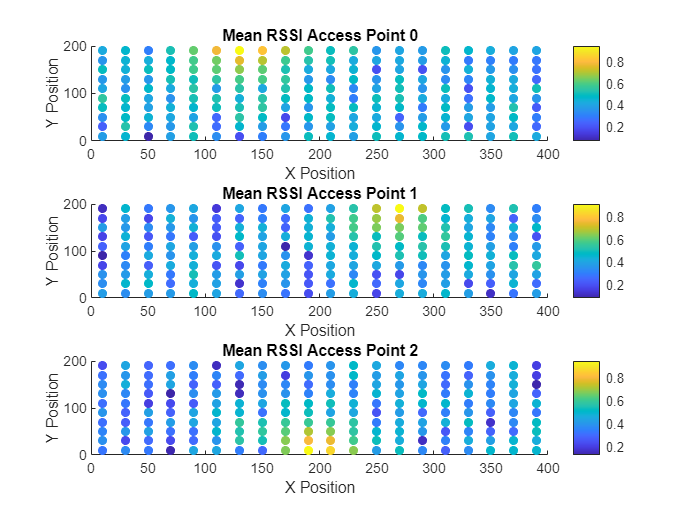

%Prepare the raw dataset
allDataMean=[];x=[];y=[];
for i=1:100:size(InputDataNorm,1)-99
    DataMean = mean(InputDataNorm(i:i+99,:));
    %DataMean = mean(InputData(i:i+99,:));
    allDataMean=[allDataMean;DataMean];
    x=[x;Output(i,2)];
    y=[y;Output(i,3)];
end

figure
subplot(3,1,1);AP=0;
z=allDataMean(:,AP+1);
scatter(x,y,30,z,'filled');
title('Mean RSSI Access Point 0');xlabel('X Position');zlabel('Mean RSSI');ylabel('Y Position');
colorbar()
subplot(3,1,2);AP=1;
z=allDataMean(:,AP+1);
scatter(x,y,30,z,'filled');
title('Mean RSSI Access Point 1');xlabel('X Position');zlabel('Mean RSSI');ylabel('Y Position');
colorbar()
subplot(3,1,3);AP=2;
z=allDataMean(:,AP+1);
scatter(x,y,30,z,'filled');
title('Mean RSSI Access Point 2');xlabel('X Position');zlabel('Mean RSSI');ylabel('Y Position');
colorbar()

clear i NewFeaturesLabels DataMean AP x y z

# 6- Statital Features Information

%'Mean RSSI Access Point 0'
AP0s = datastats(allDataMean(:,1))

AP0s = struct with fields:
       num: 200
       max: 0.9412
       min: 0.0771
      mean: 0.4394
    median: 0.4403
     range: 0.8641
       std: 0.1157


%'Mean RSSI Access Point 1'
AP1s = datastats(allDataMean(:,2))

AP1s = struct with fields:
       num: 200
       max: 0.9185
       min: 0.0800
      mean: 0.3800
    median: 0.3909
     range: 0.8385
       std: 0.1268


%'Mean RSSI Access Point 3'
AP2s = datastats(allDataMean(:,3))

AP2s = struct with fields:
       num: 200
       max: 0.9504
       min: 0.1278
      mean: 0.4095
    median: 0.3991
     range: 0.8226
       std: 0.1308


clear AP0s AP1s AP2s

# 7 - Feature Selection (Please set the maximum correlation value allowed.)

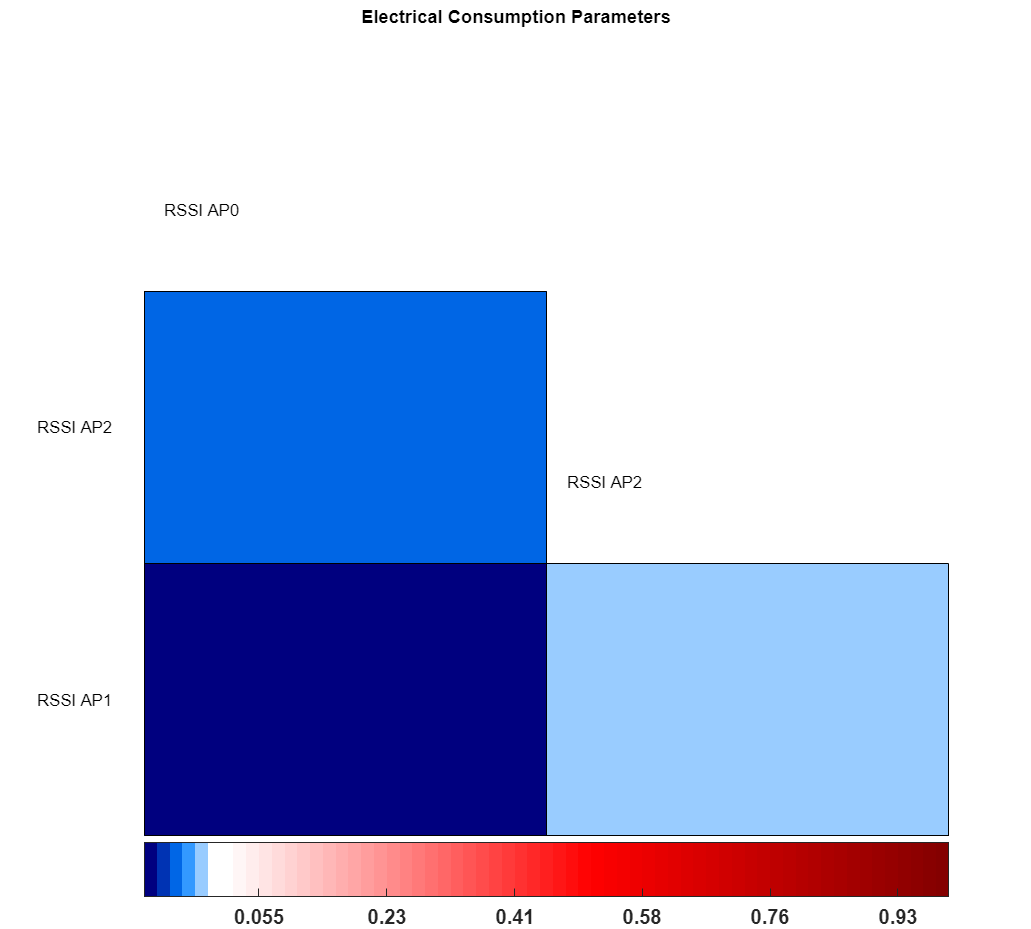

threshold = 0.75;%75<-------Maximum correlation value allowed
% Labels
FeaturesLabels = {'RSSI AP0','RSSI AP1','RSSI AP2'};
[NewDataFeatures,NewFeaturesLabels,LabelsRemove] = Feature_Selection(InputDataNorm,FeaturesLabels,threshold);

LabelsRemove(:)


ans =

  0×1 empty cell array



clear threshold LabelsRemove ans allFeatureNorm FeaturesLabels NewFeaturesLabels

# 8 - Regression Learner (Input output Data)

training_size=0.85; %85 (Training and testing), 15% Validation

%----------------Randomly arrange rows-------------------------------------
RandomNewDataFeatures=NewDataFeatures(IndexRows,:);
RandomOutput=Output(IndexRows,:);
% ---------------inputs: All previously selected features------------------
input_train=RandomNewDataFeatures(1:round(size(RandomNewDataFeatures,1)*training_size)-1,:);

% ----------------output: Energy in the next time step---------------------
output_train_x=RandomOutput(1:round(size(RandomOutput,1)*training_size)-1,2);%cloumn 2 is x
output_train_y=RandomOutput(1:round(size(RandomOutput,1)*training_size)-1,3);%column 3 is y

%regressionLearner
clear allDataMean InputDataNorm InputData Output NewDataFeatures

# RMSE (Training) - X position: 

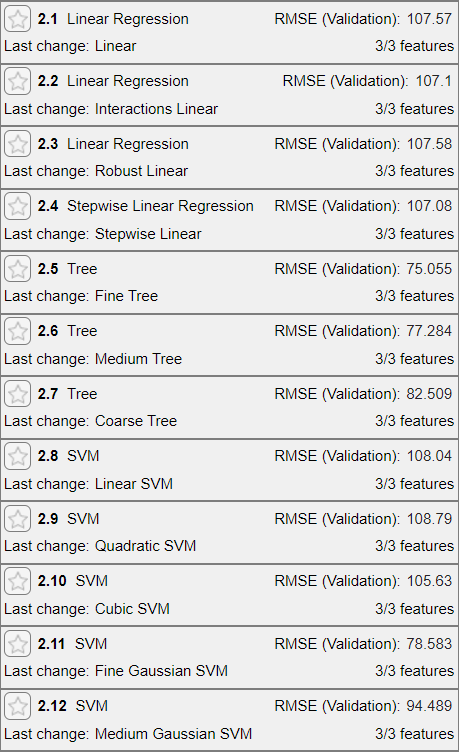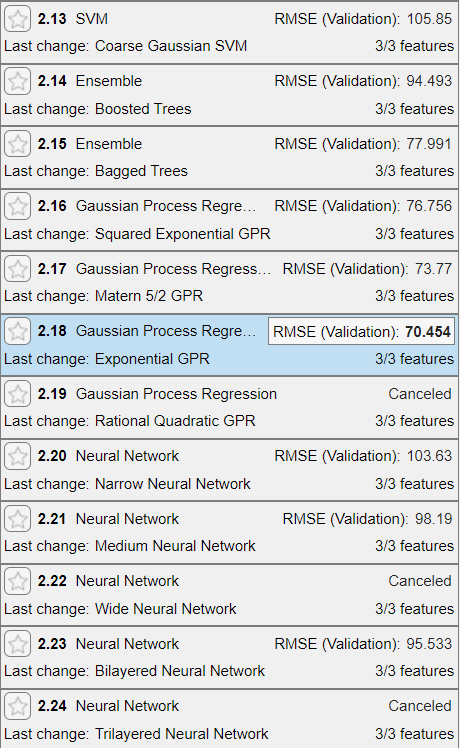

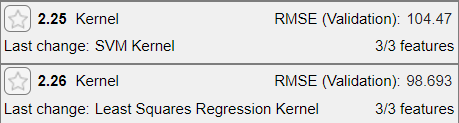

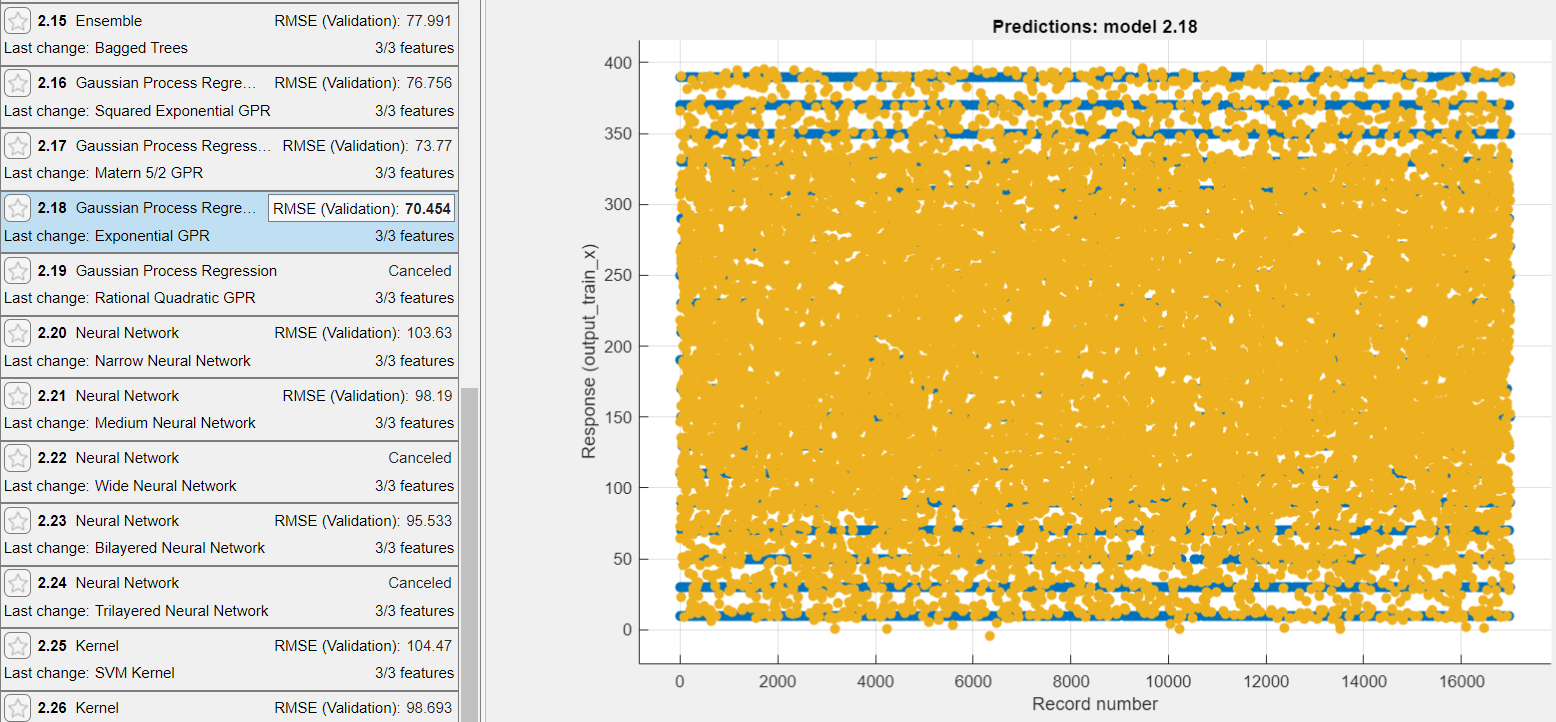

# RMSE (Training) - Y position: 

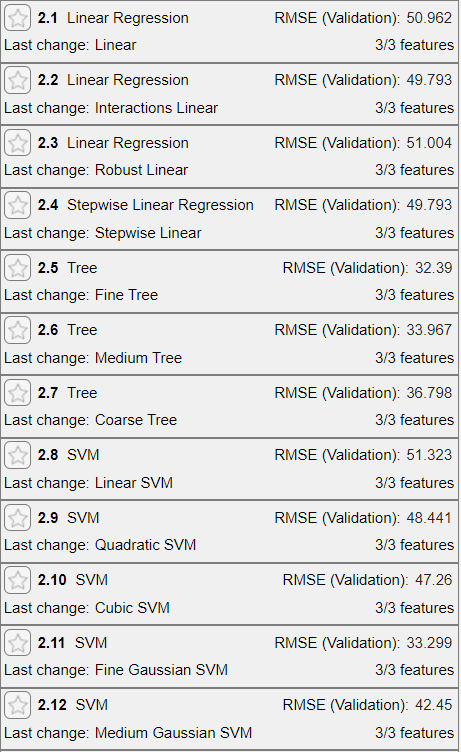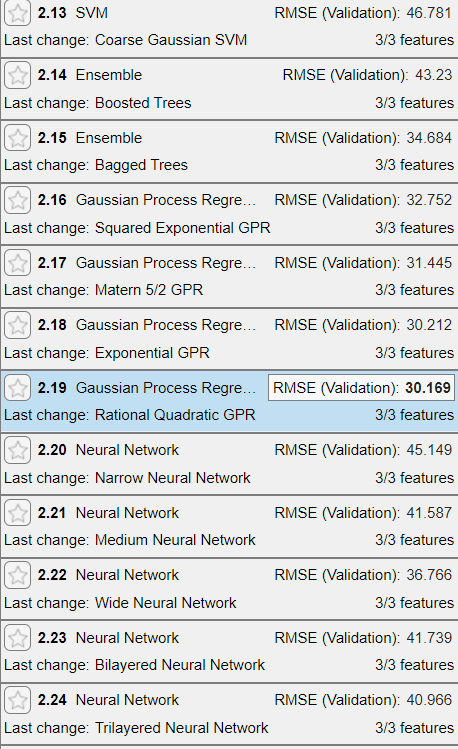

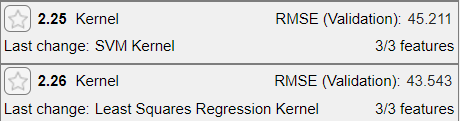

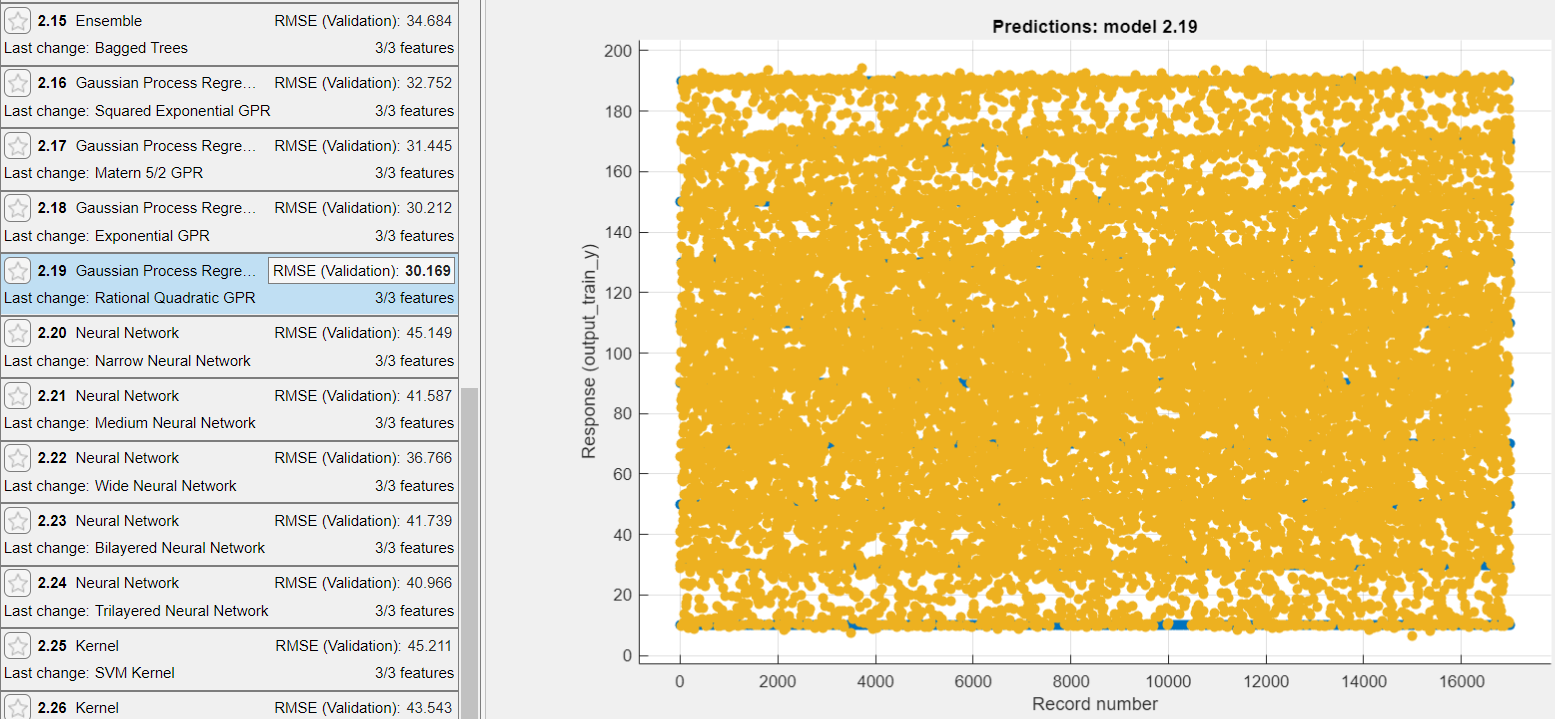

# RMSE (Testing) - XY position:

% ---------------inputs: All previously selected features------------------
input_val=RandomNewDataFeatures(round(size(RandomNewDataFeatures,1)*training_size):size(RandomNewDataFeatures,1),:);

% ----------------output: Energy in the next time step---------------------
output_val_x=RandomOutput(round(size(RandomOutput,1)*training_size):size(RandomOutput,1),2);%cloumn 2 is x
output_val_y=RandomOutput(round(size(RandomOutput,1)*training_size):size(RandomOutput,1),3);%column 3 is y

% Generate model X position
[model_x_position, RMSE_x_position] = trainRegressionModel_X_GPR70(input_train, output_train_x);
RMSE_x_position

RMSE_x_position = 70.6551

% Generate model Y position
[model_y_position, RMSE_y_position] = trainRegressionModel_Y_GPR30(input_train, output_train_y);
RMSE_y_position

RMSE_y_position = 30.2005

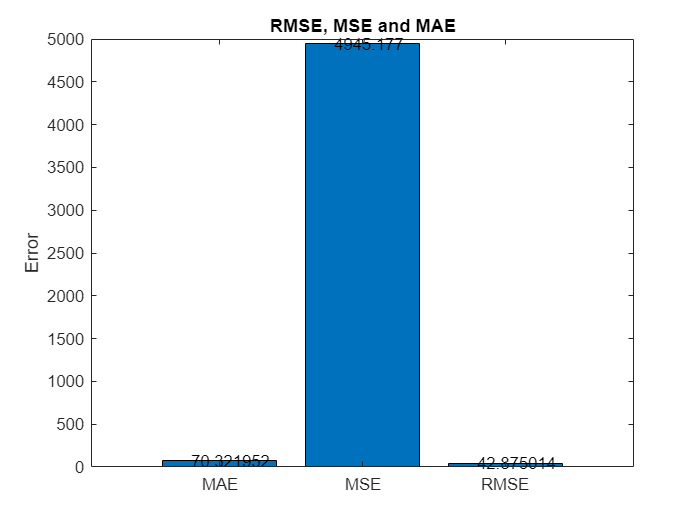

estimate_x_position=model_x_position.predictFcn(input_val);
estimate_y_position=model_y_position.predictFcn(input_val);

[rmse_x,mse_x,mae_X]=fBar_RmseMseMae(estimate_x_position,output_val_x);

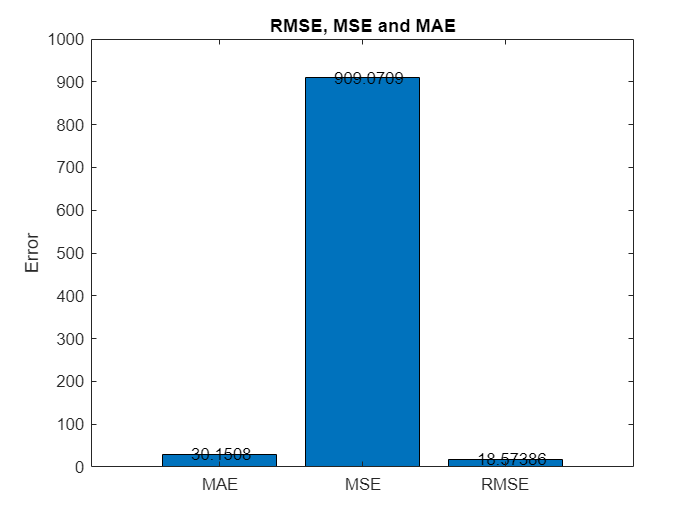

[rmse_y,mse_y,mae_y]=fBar_RmseMseMae(estimate_y_position,output_val_y);

# All Values

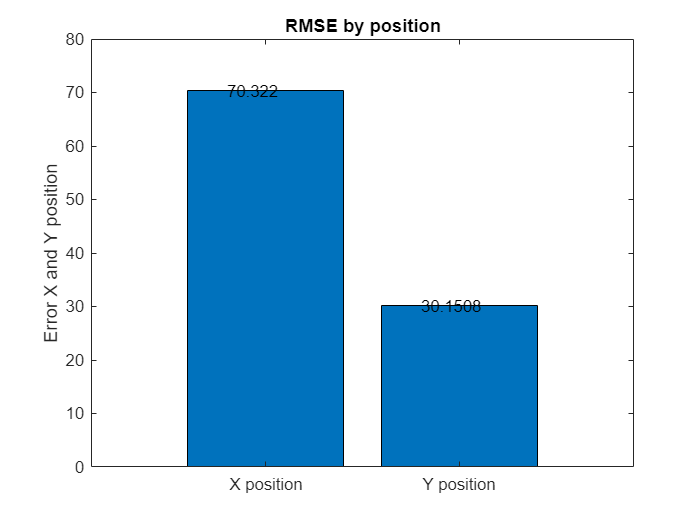

values = [rmse_x rmse_y];%1-R2
figure;
c = categorical({'X position','Y position'});
b=bar(c,values);
ylabel('Error X and Y position')
title('RMSE by position')
xtips1 = b(1).XEndPoints - 0.2;
ytips1 = b(1).YEndPoints + 0.0003;
labels1 = string(b(1).YData);
text(xtips1,ytips1,labels1,'VerticalAlignment','middle')

clear DeNormMin DeNormMax training_size mae_y mae_X mse_y mse_x RallData xtips1 ytips1
clear labels1 c b values

# FutureWork

%To perform measurements over larger areas
%Increase the number of receivers to improve prediction accuracy
% Use more than one transmitter, to track more objects